# Compile Figures for Upper Kuparuk River Basin, Alaska

%%%%%%
%Script for compiling the figure generator
%%%%%%

clear all
close all


% Base working directories
workdir = '~/Documents/GitHub/Permafrost_ERRA/datERRA/UK_antecedent_months';
workdirfigures = fullfile(workdir, 'figures');

% Ensure base figure directory exists
if ~exist(workdirfigures, 'dir')
    mkdir(workdirfigures);
end

%% Define datasets
labels = {'June', 'July', 'August'};
projfolders = {'June2July', 'July2August', 'August'};
filenames = {
    '1hr_simple_June2July_RRD.txt',
    '1hr_simple_July2August_RRD.txt',
    '1hr_simple_August_RRD.txt'
};
filestats = {
    '1hr_simple_June2July_peakstats.txt',
    '1hr_simple_July2August_peakstats.txt',
    '1hr_simple_August_peakstats.txt'
};


%% Create figure subdirectories
for i = 1:numel(projfolders)
    subdir = fullfile(workdirfigures, projfolders{i});
    if ~exist(subdir, 'dir')
        mkdir(subdir);
    end
end

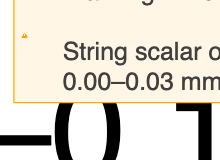

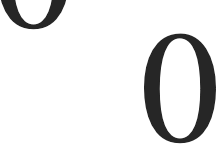

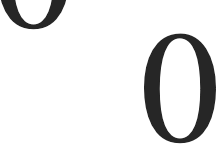

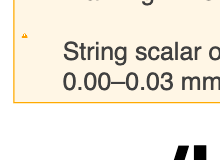


%% Run antecedent figure generation
[maxRRD_all, maxRRDlgt_all, maxRRDse_all, RRD_all, se_all, lagt_all, colNums_all, lagQrange_all] = ...
    figtRRD_plot_antecedent_monthly(labels, filenames, filestats, workdir, workdirfigures, 1);

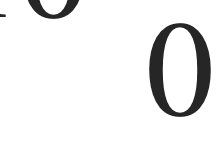


figtRRD_compare_maxRRD(colNums_all, maxRRD_all, maxRRDse_all, labels, workdirfigures, 1);


% %% Run antecedent checks for each case
% for i = 1:numel(labels)
%     workdirfig = fullfile(workdirfigures, projfolders{i});
%     colNums = colNums_all{i};
%     lagQrange = lagQrange_all{i};
% 
%     % antecedent_check(workdir, workdirfig, printfig, laghr, colNums, lagQrange);
%     % antecedent_check_runoff(workdir, workdirfig, printfig, laghr, colNums, lagQrange);
% end